Open image

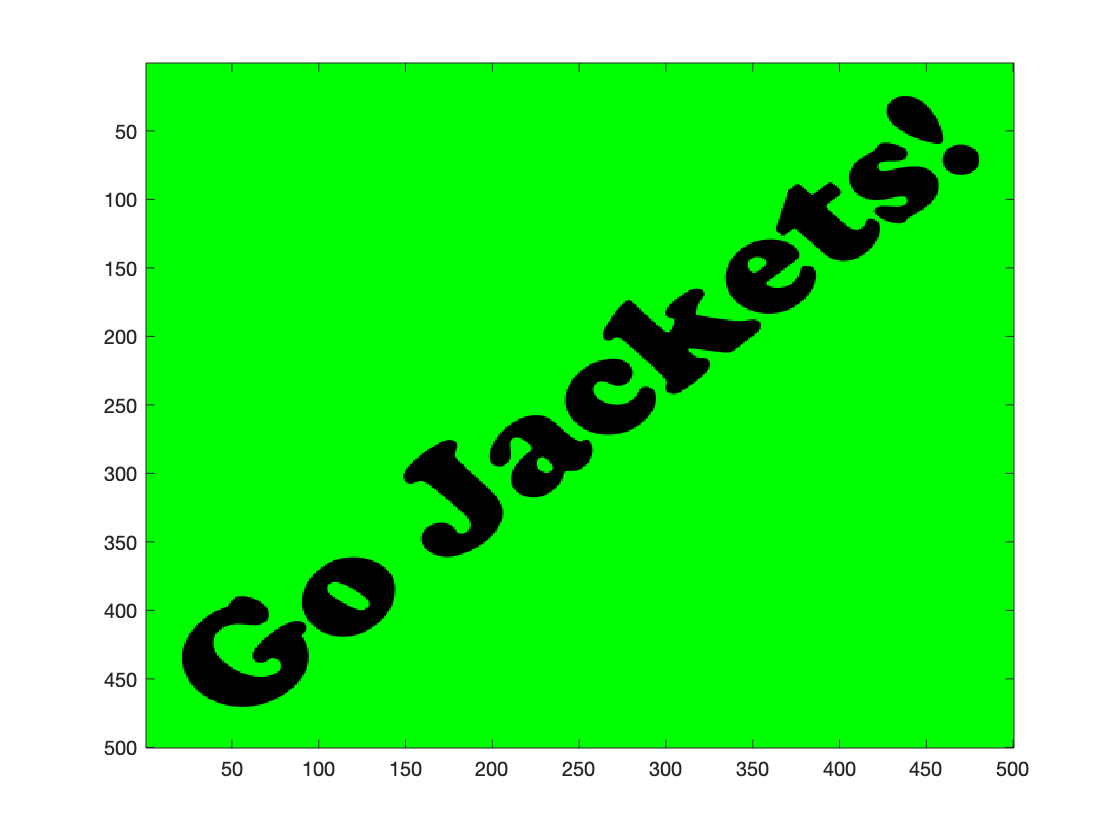

text = imread('goJackets.png');
% imshow(text)
image(text);

Create image mask

%2D mask
mask2d = (text(:,:,1)<128) & (text(:,:,2)>128) & (text(:,:,3)<128);

%3D mask
mask3d(:,:,1) =  mask2d;
mask3d(:,:,2) =  mask2d;
mask3d(:,:,3) =  mask2d;
%or
mask3d = cat(3,mask2d, mask2d, mask2d);

Use 3D mask to assign a background color

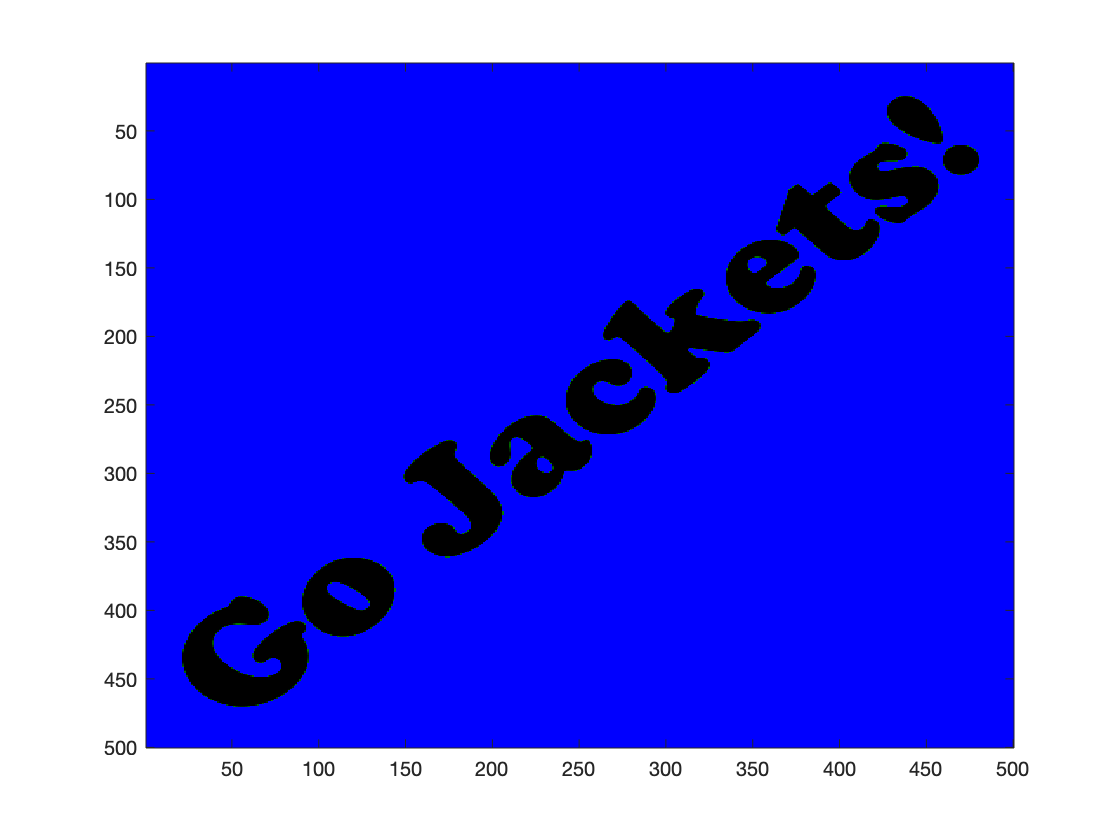

[r,c,l] = size(text);
blue(1:r,1:c,1) = uint8(0);
blue(1:r,1:c,2) = uint8(0);
blue(1:r,1:c,3) = uint8(255);
newtext = text;
newtext(mask3d) = blue(mask3d);
image(newtext)

Use 3D mask to assign a text color

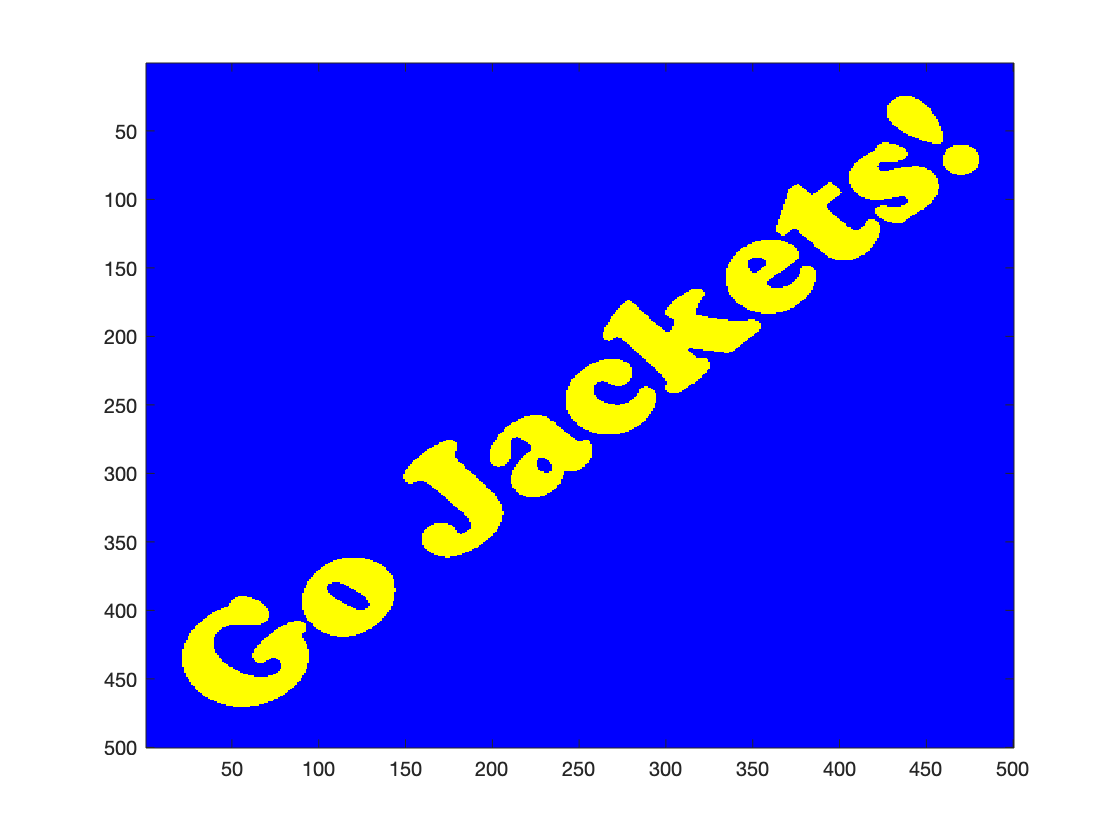

[r,c,l] = size(text);
yellow(1:r,1:c,1) = uint8(255);
yellow(1:r,1:c,2) = uint8(255);
yellow(1:r,1:c,3) = uint8(0);
newtext(~mask3d) = yellow(~mask3d);
image(newtext)

Use mask to a assign different color value to each layer (rgb)

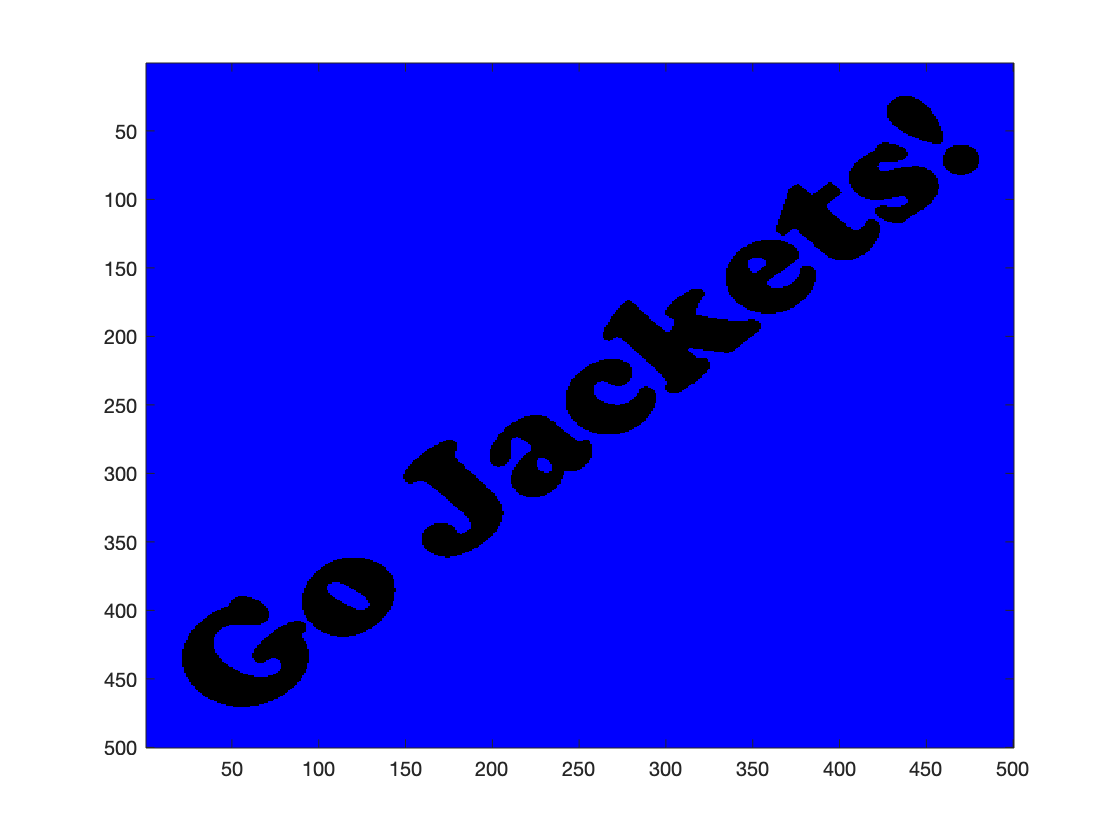

%Assign a color value to each masked layer
%Method 1 - Multiply mask by color value
colorBkgnd(:,:,1) = uint8(mask2d*0);
colorBkgnd(:,:,2) = uint8(mask2d*0);
colorBkgnd(:,:,3) = uint8(mask2d*255);
image(colorBkgnd);

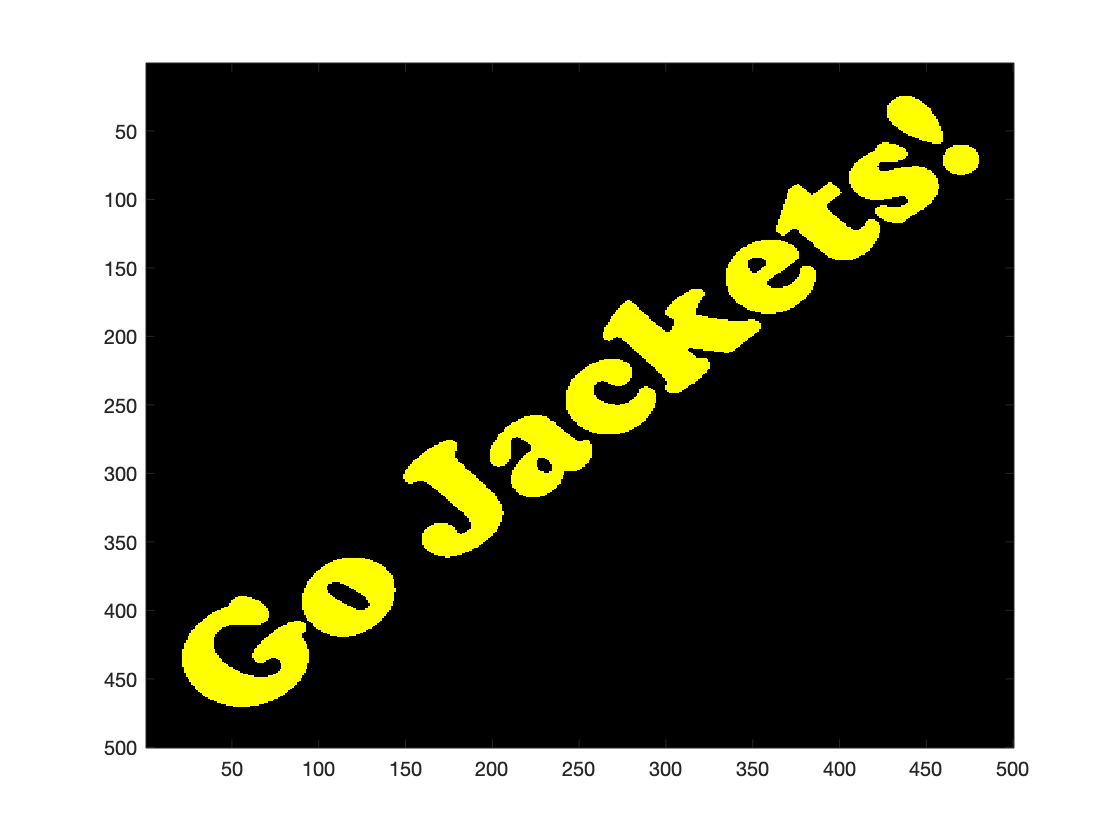


colorText(:,:,1) = uint8(~mask2d*255);
colorText(:,:,2) = uint8(~mask2d*255);
colorText(:,:,3) = uint8(~mask2d*0);
image(colorText);


%Method 2 - Use 2D mask to index corresponding colors on each layer
% colorBkgnd(:,:,1) = uint8(~mask2d*255);
% colorBkgnd(:,:,2) = uint8(~mask2d*255);
% colorBkgnd(:,:,3) = uint8(~mask2d*0);
% image(newImage);


Use another image of the same size to assign a new color value to each layer

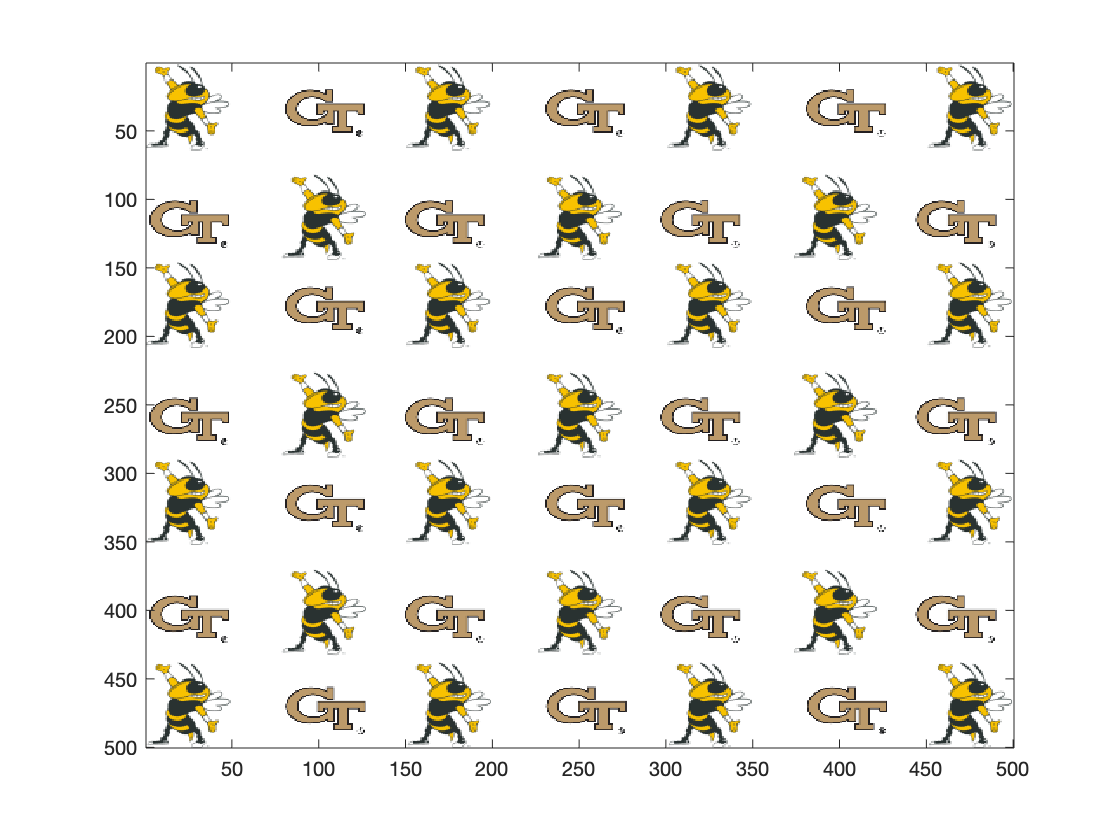

%Open background image
bkgnd = imread('goJacketsBackground.png');
image(bkgnd);

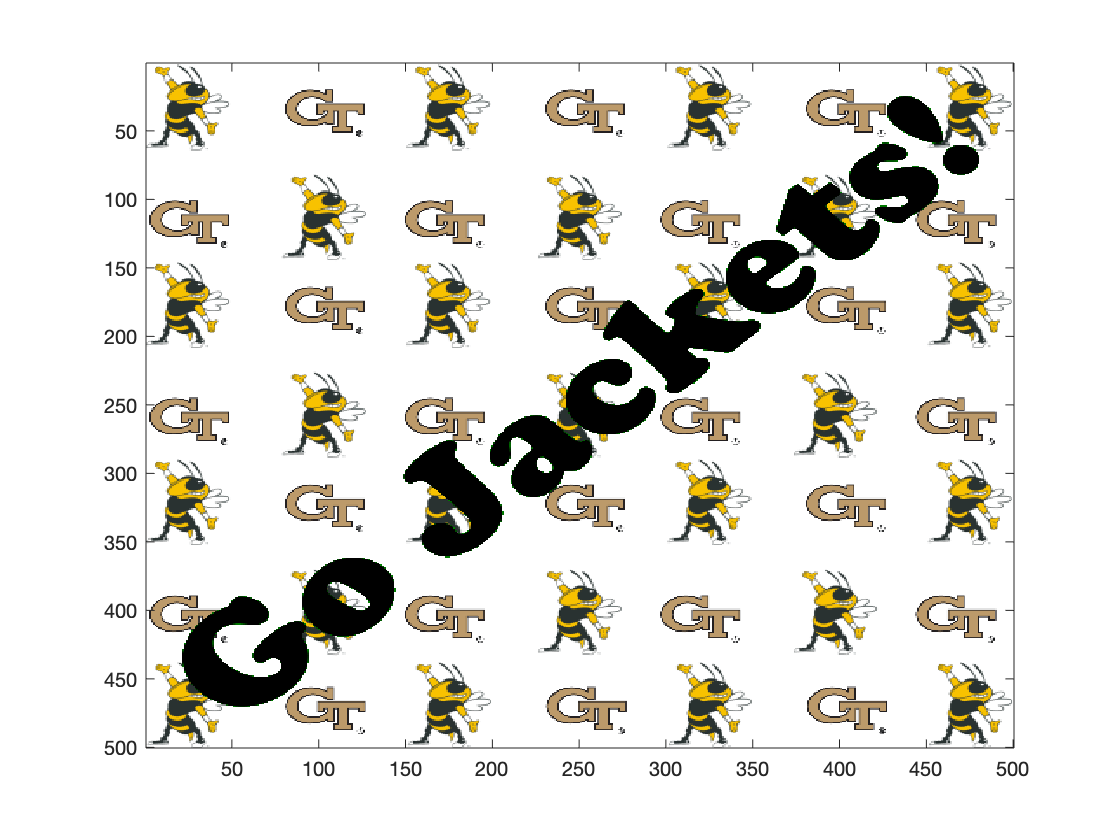


%Method 1 - Multiply mask by color value
% imgBkgnd(:,:,1) = uint8( mask2d.*double(bkgnd(:,:,1)) );
% imgBkgnd(:,:,2) = uint8( mask2d.*double(bkgnd(:,:,2)) );
% imgBkgnd(:,:,3) = uint8( mask2d.*double(bkgnd(:,:,3)) );
% image(imgBkgnd);
% 
% imgText(:,:,1) = uint8( ~mask2d.*double(bkgnd(:,:,1)) );
% imgText(:,:,2) = uint8( ~mask2d.*double(bkgnd(:,:,2)) );
% imgText(:,:,3) = uint8( ~mask2d.*double(bkgnd(:,:,3)) );
% image(imgText);

%Method 2 - Use 2D mask to index corresponding colors on each layer
% imgBkgnd = text;
% 
% bkgndR = bkgnd(:,:,1);
% bkgndG = bkgnd(:,:,2);
% bkgndB = bkgnd(:,:,3);
% 
% imgBkgndR = imgBkgnd(:,:,1);
% imgBkgndG = imgBkgnd(:,:,2);
% imgBkgndB = imgBkgnd(:,:,3);
% 
% imgBkgndR(mask2d) = bkgndR(mask2d);
% imgBkgndG(mask2d) = bkgndG(mask2d);
% imgBkgndB(mask2d) = bkgndB(mask2d);
% 
% imgBkgnd = cat(3,imgBkgndR, imgBkgndG, imgBkgndB);
% image(imgBkgnd)

%Method 3 - Use 3D mask to index all layers at once
newImage = text;
newImage(mask3d) = bkgnd(mask3d);
image(newImage)